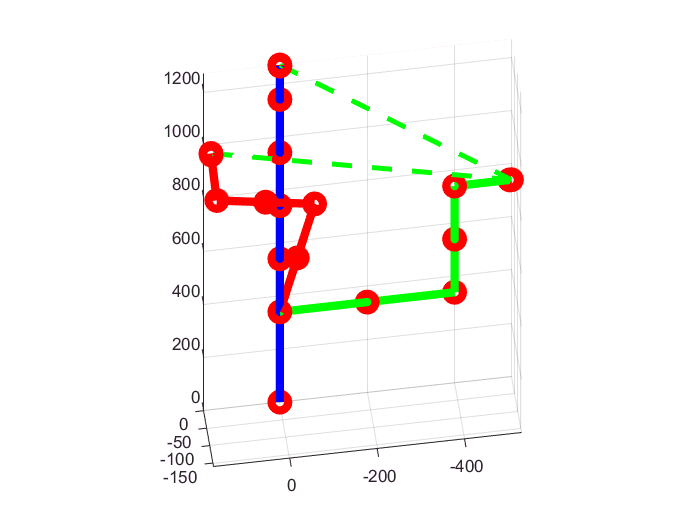

clear all
close all
L_test1 = [340 200 200 200 200 126 4];

q_test0 = [0 0 0 0 0 0 0];
q_test1 = [pi/2 0 0 0 0 0 0];
q_test2 = [0 pi/2 0  pi/2 0 pi/2 0];
q_test3 = [0 0.2 0.5  1 0.5 1 0];

draw_trayectory_robot(q_test1,q_test2,q_test3,L_test1) %draw trayectory for 3 positions

syms q1_symb q2_symb q3_symb q4_symb q5_symb q6_symb q7_symb real
syms d1_symb d2_symb d3_symb d4_symb d5_symb d6_symb d7_symb real

q_symb=[q1_symb q2_symb q3_symb q4_symb q5_symb q6_symb q7_symb];
L_symb=[d1_symb d2_symb d3_symb d4_symb d5_symb d6_symb d7_symb];
%Jq=simplify(Jacobian(q_symb,L_symb))

%Jacobbian
Jq1=Jacobian(q_test1,L_test1)

Jq1 =          0  930.0000         0  530.0000         0  130.0000         0
         0   -0.0000         0   -0.0000         0   -0.0000         0
         0         0         0         0         0         0         0
         0    0.0000         0    0.0000         0    0.0000         0
         0    1.0000         0    1.0000         0    1.0000         0
    1.0000         0    1.0000         0    1.0000         0    1.0000


%Weighted Pseudo Inverser 
q_test3 = [0 0.2 0.5 1 0.5 1 0];
q_test3'

ans =          0
    0.2000
    0.5000
    1.0000
    0.5000
    1.0000
         0


p_target= FK(q_test3,L_test1) %target end effector point

p_target =    1.0e+03 *

    0.0006   -0.0007    0.0003   -0.1188
    0.0007    0.0007    0.0001    0.1744
   -0.0003    0.0002    0.0009    1.1251
         0         0         0    0.0010


%Input: target position and orientation we want, initial joint positions, lenghts of links, type of IK
q_ik_pseudoInverse = IK_pseudoInverseJacobbian(p_target, q_test0, L_test1, 1)

q_ik_pseudoInverse =    -0.0789
   -0.1280
   -3.0122
   -0.2989
   -1.2430
   -1.5294
   -1.8686


p_ik_pseudoInverse = FK(q_ik_pseudoInverse,L_test1)

p_ik_pseudoInverse =    1.0e+03 *

    0.0001   -0.0003   -0.0009   -0.1188
    0.0002    0.0009   -0.0003    0.1744
    0.0010   -0.0001    0.0002    1.1251
         0         0         0    0.0010



q_ik_pseudoInverse_weighted = IK_pseudoInverseJacobbian(p_target, q_test0, L_test1, 2)

q_ik_pseudoInverse_weighted =     1.2895
   -0.2180
   -0.7713
    0.4006
   -2.2111
   -1.5448
  -12.4262


p_ik_pseudoInverse_weighted = FK(q_ik_pseudoInverse_weighted,L_test1)

p_ik_pseudoInverse_weighted =    1.0e+03 *

   -0.0002    0.0004    0.0009   -0.1188
   -0.0010   -0.0003   -0.0001    0.1744
    0.0002   -0.0009    0.0005    1.1251
         0         0         0    0.0010


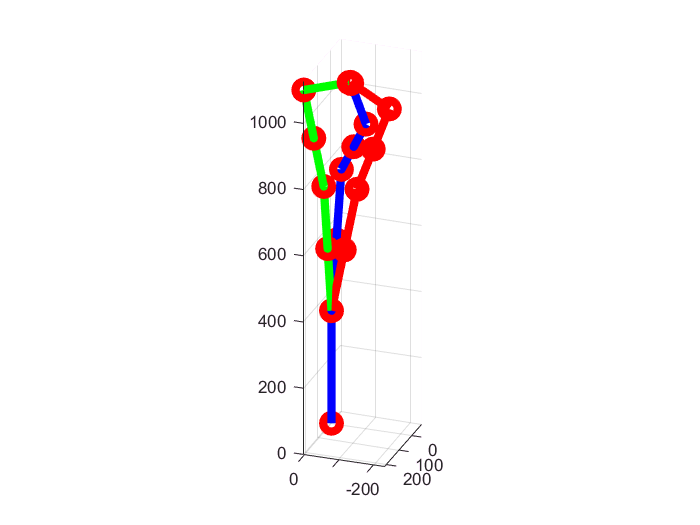


%draw target position, position using pseudo inverse and position using weighted pseudo inverse
draw_trayectory_robot(q_test3,q_ik_pseudoInverse,q_ik_pseudoInverse_weighted,L_test1)

%Damped Least Squares





%Null Space 